## นายพิชญ์ รังษีจำรัส 62070502215    Homework 05 :

Bring up Source Image and Gray scaled it

Attempt 1 : picture with 5*5 pixel

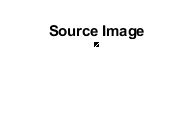

%Attempt 1
clear
clc
% input image from source
I = imread('forhough.png');
imshow(I)
title("Source Image")

% Convert rgb image to grayscale image
r = I(:,:,1);
g = I(:,:,2);
b = I(:,:,3);
I2 = (0.3*r) + (0.6*g) + (0.1*b)

I2 = 5×5 uint8 matrix
     0     0     0     0     0
     0     0     0     0   255
     0     0     0   255     0
     0     0   255     0     0
     0   255     0     0     0


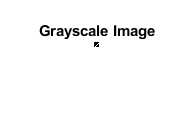

% Grayscale Image Result
imshow(I2)
title("Grayscale Image")

% Get image's resolution
[x y] = size(I2)

x = 5

y = 5

% Binary Image transform
level = graythresh(I2)

level = 0.4980

I3 = imbinarize(I2,level)

I3 = 5×5 logical array
   0   0   0   0   0
   0   0   0   0   1
   0   0   0   1   0
   0   0   1   0   0
   0   1   0   0   0


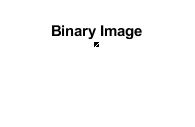

imshow(I3)
title("Binary Image")

Write a program for Hough transform.

% Get the coordinate of the white pixel
forhoughx = [] ;
forhoughy = [] ;
num = 0 ;
for i = 1:x
    for j = 1:y 
        if I3(x+1-i,j) == 1
            forhoughy(num+1) = i ;
            forhoughx(num+1) = j ;
            num = num + 1 ;
        end
    end
end    
forhoughx

forhoughx =      2     3     4     5


forhoughy

forhoughy =      1     2     3     4


% Get size of array
[a b] = size(forhoughx) ;
% find c for hough transform
c = [] ;
c = forhoughy ;
% find m for hought transform
m = [] ;
for i = 1:b
    m(i) = forhoughy(i)/forhoughx(i) ;
end
c

c =      1     2     3     4


m

m =     0.5000    0.6667    0.7500    0.8000


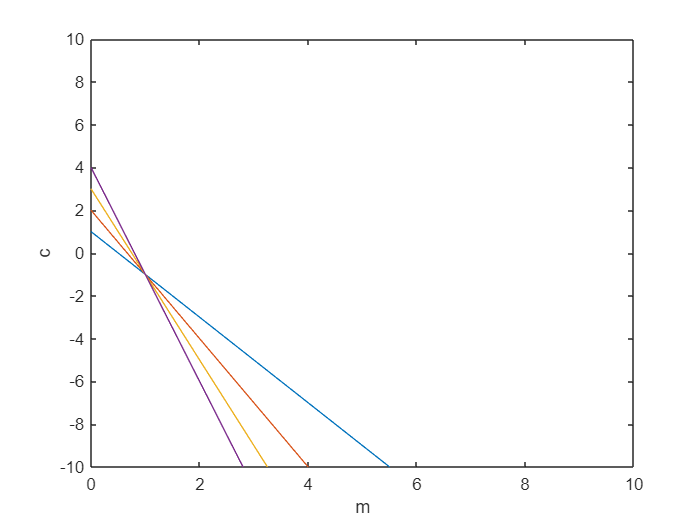

% plot the graph
figure
m = -10:0.01:10;
for i = 1:b
    c = -(forhoughx(i))*m + forhoughy(i);
    plot(m,c);
    hold on
end
xlim([0 10])
ylim([-10 10])
xlabel('m')
ylabel('c')
hold off

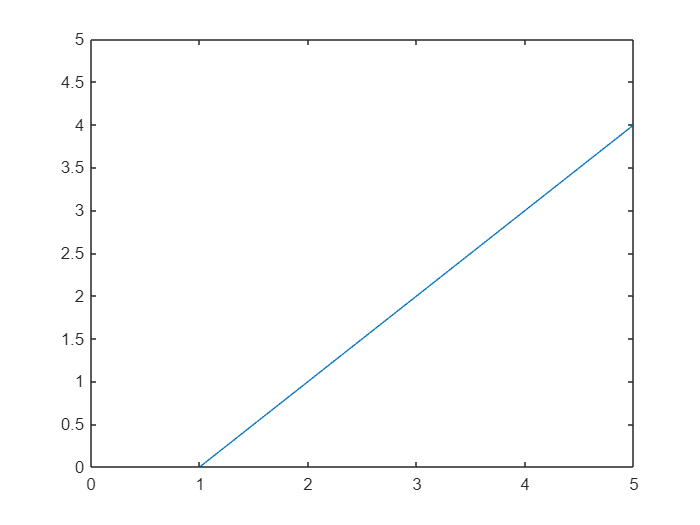

% Generate line from the point we get
% as the most intercept point is (1,-1)
% which mean m = 1 , c = - 1
m = 1 ;
c = -1 ; 
x = -100:1:100 ;
y = m*x+c ;
plot(x,y) ;
xlim([0 5]) 
ylim([0 5])

Attempt 2 : picture with 25*25 pixel

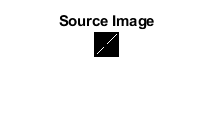

%Attempt 2
clear
clc
% input image from source
I = imread('forhough2.png');
imshow(I)
title("Source Image")

% Convert rgb image to grayscale image
r = I(:,:,1);
g = I(:,:,2);
b = I(:,:,3);
I2 = (0.3*r) + (0.6*g) + (0.1*b)

I2 = 25×25 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   255     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   255     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   255     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   255     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0    

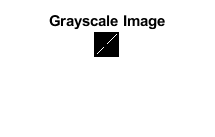

% Grayscale Image Result
imshow(I2)
title("Grayscale Image")

% Get image's resolution
[x y] = size(I2)

x = 25

y = 25

% Binary Image transform
level = graythresh(I2)

level = 0.4980

I3 = imbinarize(I2,level)

I3 = 25×25 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1  

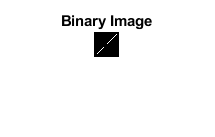

imshow(I3)
title("Binary Image")

Write a program for Hough transform.

% Get the coordinate of the white pixel
forhoughx = [] ;
forhoughy = [] ;
num = 0 ;
for i = 1:x
    for j = 1:y 
        if I3(x+1-i,j) == 1
            forhoughy(num+1) = i ;
            forhoughx(num+1) = j ;
            num = num + 1 ;
        end
    end
end    
forhoughx

forhoughx =      4     5     6     7     8     9    10    14    15    16    17    18    19    20    21    22    23


forhoughy

forhoughy =      4     5     6     7     8     9    10    14    15    16    17    18    19    20    21    22    23


% Get size of array
[a b] = size(forhoughx) ;
% find c for hough transform
c = [] ;
c = forhoughy ;
% find m for hought transform
m = [] ;
for i = 1:b
    m(i) = forhoughy(i)/forhoughx(i) ;
end
c

c =      4     5     6     7     8     9    10    14    15    16    17    18    19    20    21    22    23


m

m =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


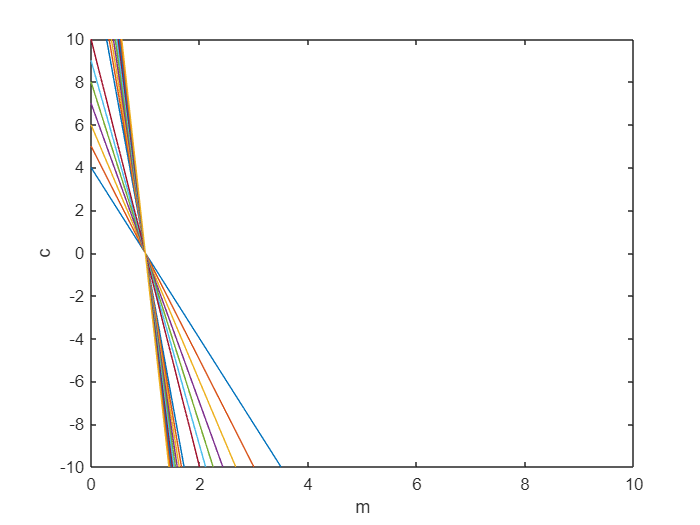

% plot the graph
figure
m = -10:0.01:10;
for i = 1:b
    c = -(forhoughx(i))*m + forhoughy(i);
    plot(m,c);
    hold on
end
xlim([0 10])
ylim([-10 10])
xlabel('m')
ylabel('c')
hold off

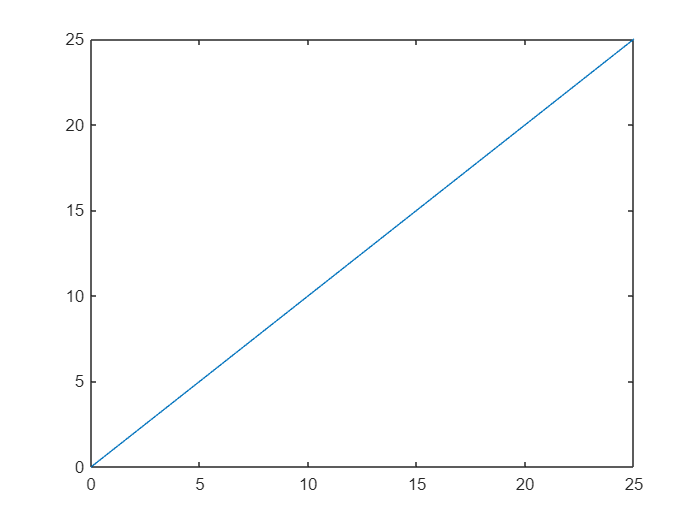

% Generate line from the point we get
% as the most intercept point is (1,0)
% which mean m = 1 , c = 0
m = 1 ;
c = 0 ; 
x = -100:1:100 ;
y = m*x+c ;
plot(x,y) ;
xlim([0 25]) 
ylim([0 25])

Attempt 3 : picture with 100*100 pixel

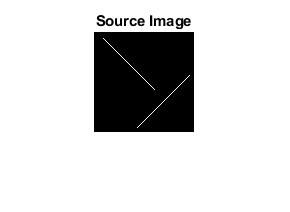

%Attempt 3
clear
clc
% input image from source
I = imread('forhough3.png');
imshow(I)
title("Source Image")

% Convert rgb image to grayscale image
r = I(:,:,1);
g = I(:,:,2);
b = I(:,:,3);
I2 = (0.3*r) + (0.6*g) + (0.1*b)

I2 = 100×100 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     

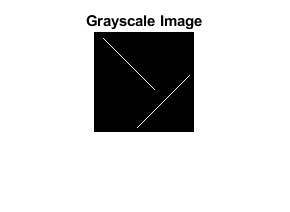

% Grayscale Image Result
imshow(I2)
title("Grayscale Image")

% Get image's resolution
[x y] = size(I2)

x = 100

y = 100

% Binary Image transform
level = graythresh(I2)

level = 0.4980

I3 = imbinarize(I2,level)

I3 = 100×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

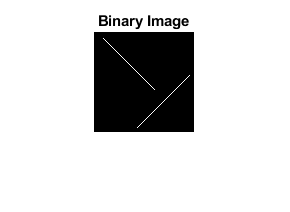

imshow(I3)
title("Binary Image")

Write a program for Hough transform.

% Get the coordinate of the white pixel
forhoughx = [] ;
forhoughy = [] ;
num = 0 ;
for i = 1:x
    for j = 1:y 
        if I3(x+1-i,j) == 1
            forhoughy(num+1) = i ;
            forhoughx(num+1) = j ;
            num = num + 1 ;
        end
    end
end    
forhoughx

forhoughx =     44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    61    82    60    83    59    84    58    85    57    86    56    87


forhoughy

forhoughy =      5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    43    44    44    45    45    46    46    47    47    48    48


% Get size of array
[a b] = size(forhoughx) ;
% find c for hough transform
c = [] ;
c = forhoughy ;
% find m for hought transform
m = [] ;
for i = 1:b
    m(i) = forhoughy(i)/forhoughx(i) ;
end
c

c =      5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    43    44    44    45    45    46    46    47    47    48    48


m

m =     0.1136    0.1333    0.1522    0.1702    0.1875    0.2041    0.2200    0.2353    0.2500    0.2642    0.2778    0.2909    0.3036    0.3158    0.3276    0.3390    0.3500    0.3607    0.3710    0.3810    0.3906    0.4000    0.4091    0.4179    0.4265    0.4348    0.4429    0.4507    0.4583    0.4658    0.4730    0.4800    0.4868    0.4935    0.5000    0.5063    0.5125    0.5185    0.7049    0.5244    0.7333    0.5301    0.7627    0.5357    0.7931    0.5412    0.8246    0.5465    0.8571    0.5517


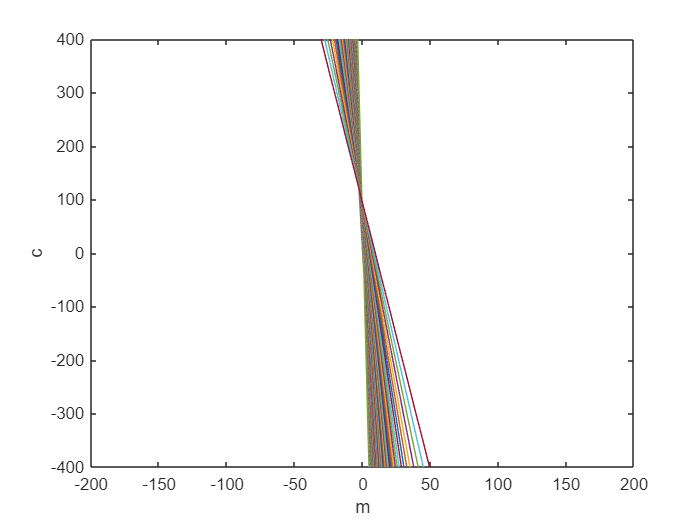

% plot the graph
figure
m = -100:1:100;
for i = 1:b
    c = -(forhoughx(i))*m + forhoughy(i);
    plot(m,c);
    hold on
end
xlim([-200 200])
ylim([-400 400])
xlabel('m')
ylabel('c')
hold off

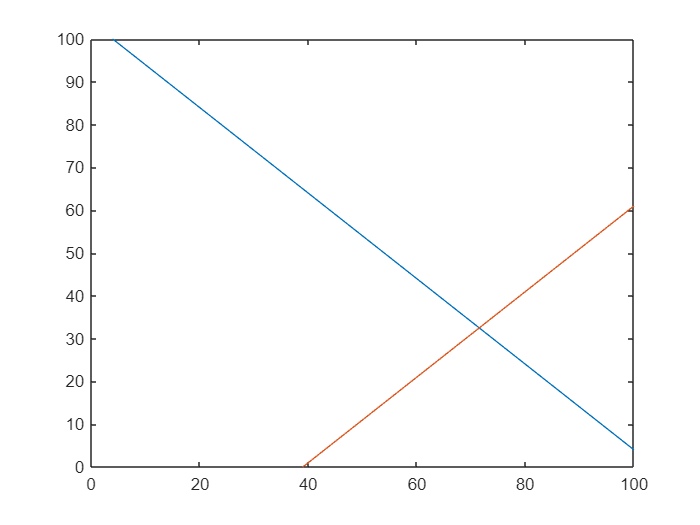

% Generate line from the point we get
% as the most intercept point is (-1,104) and (1,-39)
% which mean m = -1 , c = 104 and m = 1 , c = -39
m = -1 ;
c = 104 ; 
x = -100:1:100 ;
y = m*x+c ;
plot(x,y) ; 
hold on
m = 1 ;
c = -39 ; 
x = -100:1:100 ;
y = m*x+c ;
plot(x,y) ;
xlim([0 100]) 
ylim([0 100])
hold off